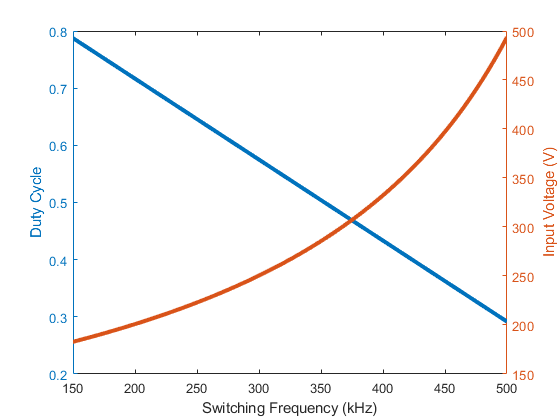

Rload = 24; %ohms
Iout = 6; %A
Pout = Iout^2*Rload;
Vout = Iout*Rload;
DeltaI = 30;
IndMaxPeak = (Iout + DeltaI)/2;
IndMinPeak = (Iout - DeltaI)/2;
fsw = 50e3:5e3:500e3;
L = 6.8e-6;
D = 1 - L.*fsw*DeltaI/Vout;
Vin = Vout./D;

C = (0.68e-6 + 2*0.22e-6)*1;
szdim2 = size(D,2);
for i = 1:szdim2
    if D(i) <= 0.5
       RippleCoeff(i) = -2.106*(D(i)) + 1.082;
    else
       RippleCoeff(i) = -2.106*(1 - D(i)) + 1.082; 
    end
end

DeltaV = DeltaI.*RippleCoeff./(C*8*fsw*2);
PercentRipple = DeltaV./Vout*100;
[~,ix] = min(abs(PercentRipple-5));
IcapRMS = DeltaI*RippleCoeff/sqrt(3);

figure
yyaxis left
plot(fsw/1e3,D, 'LineWidth', 3);
ylabel('Duty Cycle')
yyaxis right
plot(fsw/1e3,Vin,'LineWidth', 3);
xlabel('Switching Frequency (kHz)')
ylabel('Input Voltage (V)')
xlim([fsw(ix)/1e3 500])

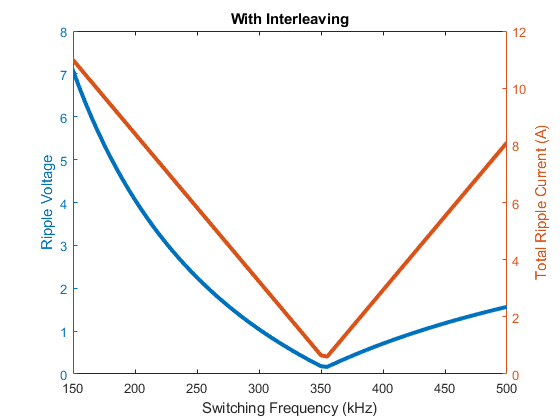


figure
title('With Interleaving')
yyaxis left
plot(fsw/1e3,PercentRipple*Vout/100, 'LineWidth', 3);
ylabel('Ripple Voltage')
yyaxis right
plot(fsw/1e3,IcapRMS, 'LineWidth', 3);
ylabel('Total Ripple Current (A)')
xlabel('Switching Frequency (kHz)')
xlim([fsw(ix)/1e3 500])

## Soft Starting

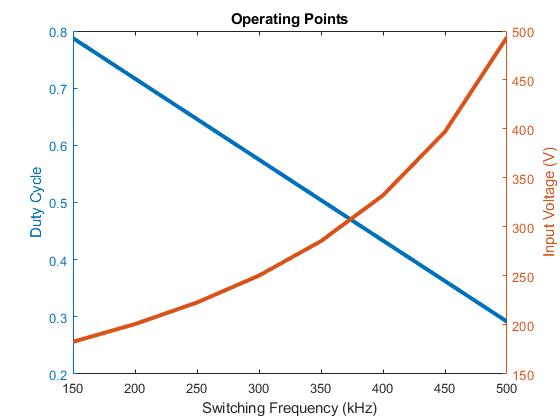

freqOp = 150e3:50e3:500e3;
szdim2 = size(freqOp,2);
for i = 1:szdim2
    [~,ix] = min(abs(fsw - freqOp(i)));
    DOp(i) = D(ix);
    VinOp(i) = Vout/DOp(i);
end

figure
title('Operating Points')
yyaxis left
plot(freqOp/1e3,DOp, 'LineWidth', 3);
ylabel('Duty Cycle')
yyaxis right
plot(freqOp/1e3,VinOp,'LineWidth', 3);
xlabel('Switching Frequency (kHz)')
ylabel('Input Voltage (V)')

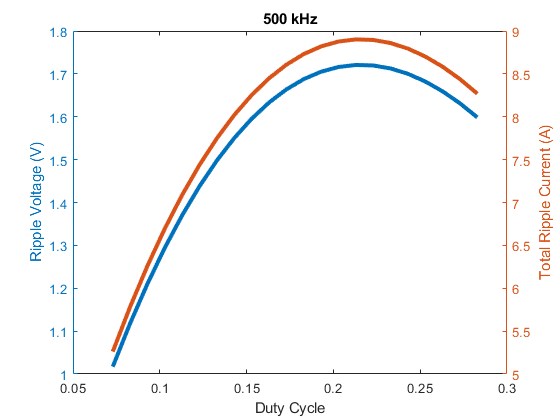


Dmin = DOp*0.25;
op = 8;
j = 1;
fact = freqOp(op);
clear DeltaVSS
clear IcapRMSSS
clear K
for duty = Dmin(op):0.01:DOp(op)
    if duty <= 0.5
       RCoeff = -2.106*(duty) + 1.082;
    else
       RCoeff = -2.106*(1 - duty) + 1.082; 
    end
    Vout = VinOp(op)*duty;
    DeltaI = Vout*(1-duty)/fact/L;
    K(j) = DeltaI/(Vout/Rload/2);
    DeltaVSS(j) = DeltaI.*RCoeff./(C*8*fact*2);
    IcapRMSSS(j) = DeltaI*RCoeff/sqrt(3);
    j = j+1;
end

figure
title('500 kHz')
yyaxis left
plot(Dmin(op):0.01:DOp(op),DeltaVSS, 'LineWidth', 3);
ylabel('Ripple Voltage (V)')
yyaxis right
plot(Dmin(op):0.01:DOp(op),IcapRMSSS, 'LineWidth', 3);
ylabel('Total Ripple Current (A)')
xlabel('Duty Cycle')

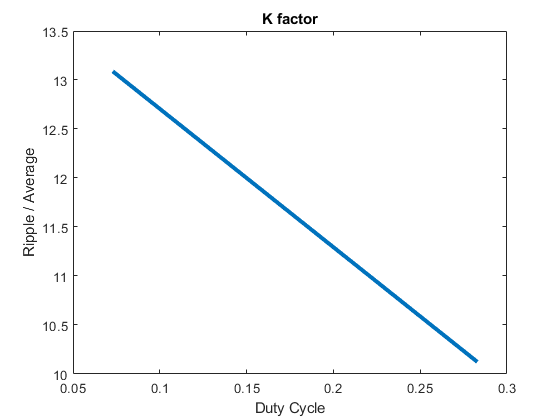


figure
plot(Dmin(op):0.01:DOp(op),K, 'LineWidth', 3);
title('K factor')
ylabel('Ripple / Average')
xlabel('Duty Cycle')